clear; clc; close all;

inputDir = '/MATLAB Drive/ADHD_data/ADHD_part1';  
outputDir = '/MATLAB Drive/ADHD_data/ADHD_part1_preprocessed'; 
exampleFileName = 'v1p.mat';


if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

fs = 128; 
fileList = dir(fullfile(inputDir, '*.mat'));
disp('Files found in the input directory:');

Files found in the input directory:


disp({fileList.name}'); 

    {'v10p.mat'}
    {'v12p.mat'}
    {'v14p.mat'}
    {'v15p.mat'}
    {'v173.mat'}
    {'v18p.mat'}
    {'v19p.mat'}
    {'v1p.mat' }
    {'v20p.mat'}
    {'v21p.mat'}
    {'v22p.mat'}
    {'v24p.mat'}
    {'v25p.mat'}
    {'v27p.mat'}
    {'v28p.mat'}
    {'v29p.mat'}
    {'v30p.mat'}
    {'v31p.mat'}
    {'v32p.mat'}
    {'v33p.mat'}
    {'v34p.mat'}
    {'v35p.mat'}
    {'v36p.mat'}
    {'v37p.mat'}
    {'v38p.mat'}
    {'v39p.mat'}
    {'v3p.mat' }
    {'v40p.mat'}
    {'v6p.mat' }
    {'v8p.mat' }



exampleFilePath = fullfile(inputDir, exampleFileName);


dataStruct = load(exampleFilePath);

fn = fieldnames(dataStruct);
rawData = dataStruct.(fn{1}); 

fprintf('Loaded example file: %s\n', exampleFileName);

Loaded example file: v1p.mat


fprintf('Data size: %d x %d (rows x cols)\n', size(rawData,1), size(rawData,2));

Data size: 12258 x 19 (rows x cols)


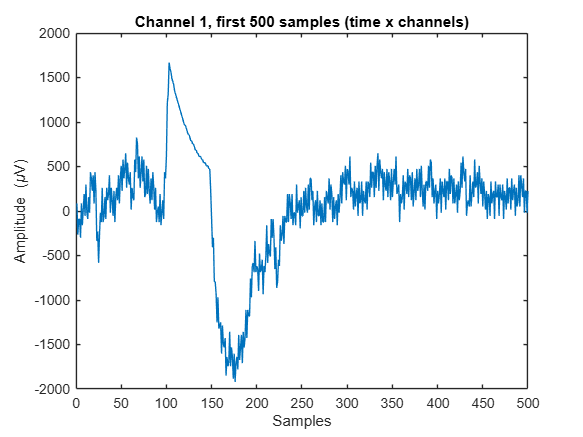


if size(rawData,1) < size(rawData,2)
    rawData = rawData'; 
    fprintf('Transposed data to channels x time.\n');
end

figure('Name','Raw EEG - v1p.mat','NumberTitle','off');
plot(rawData(1:500,1));
title('Channel 1, first 500 samples (time x channels)');
xlabel('Samples'); ylabel('Amplitude (\muV)');

exampleIndex = 1; 
exampleFile = fileList(exampleIndex).name;
examplePath = fullfile(fileList(exampleIndex).folder, exampleFile);

fprintf('--- Testing on: %s ---\n', exampleFile);

--- Testing on: v10p.mat ---



dataStruct = load(examplePath);
fieldNames = fieldnames(dataStruct);
rawData = dataStruct.(fieldNames{1}); 


[dataRows, dataCols] = size(rawData);
fprintf('Raw data size: %d x %d\n', dataRows, dataCols);

Raw data size: 14304 x 19



if dataRows > dataCols
    rawData = rawData';
    fprintf('Transposed data to: %d x %d (channels x time)\n', size(rawData,1), size(rawData,2));
end

Transposed data to: 19 x 14304 (channels x time)


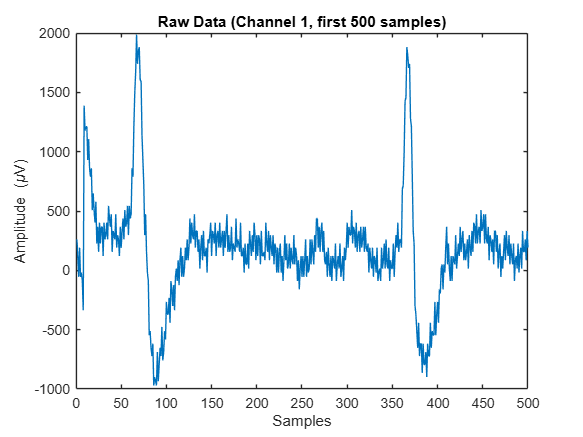


channels = size(rawData,1);
timePoints = size(rawData,2);

figure('Name','Raw Data Snippet','NumberTitle','off');
plot(rawData(1,1:min(500,timePoints))); 
xlabel('Samples'); ylabel('Amplitude (\muV)');
title(['Raw Data (Channel 1, first ',num2str(min(500,timePoints)),' samples)']);

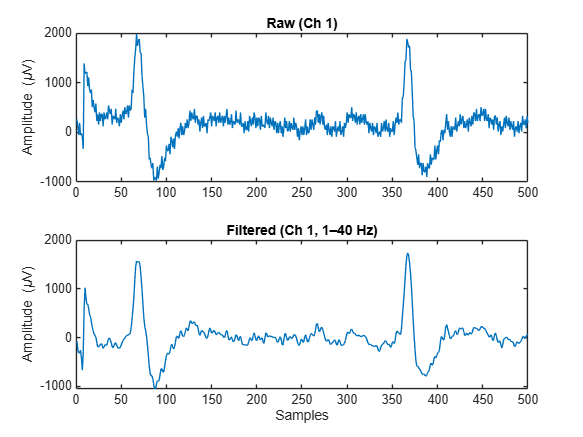



lowCut = 1; 
highCut = 40;
desiredOrder = 4; 


if timePoints < 24
    
    warning('Data length (%d) is < 24. Skipping filter or reducing order.', timePoints);
    filteredData = rawData;  
else
    [b,a] = butter(desiredOrder, [lowCut highCut]/(fs/2), 'bandpass');
    
    % while timePoints < 3*(desiredOrder*2)
    %    desiredOrder = desiredOrder - 1;
    % end
    % [b,a] = butter(desiredOrder, [lowCut highCut]/(fs/2), 'bandpass');
    
    filteredData = zeros(size(rawData));
    for ch = 1:channels
        filteredData(ch,:) = filtfilt(b, a, rawData(ch,:));
    end
end


figure('Name','Filter Comparison','NumberTitle','off');
subplot(2,1,1);
plot(rawData(1,1:min(500,timePoints)));
title('Raw (Ch 1)');
ylabel('Amplitude (\muV)');
subplot(2,1,2);
plot(filteredData(1,1:min(500,timePoints)));
title('Filtered (Ch 1, 1–40 Hz)');
xlabel('Samples'); ylabel('Amplitude (\muV)');


artifactThreshold = 1000;  
artifactMask = abs(filteredData) > artifactThreshold;

numArtifacts = sum(artifactMask(:));
fprintf('Number of artifact samples flagged: %d\n', numArtifacts);

Number of artifact samples flagged: 126


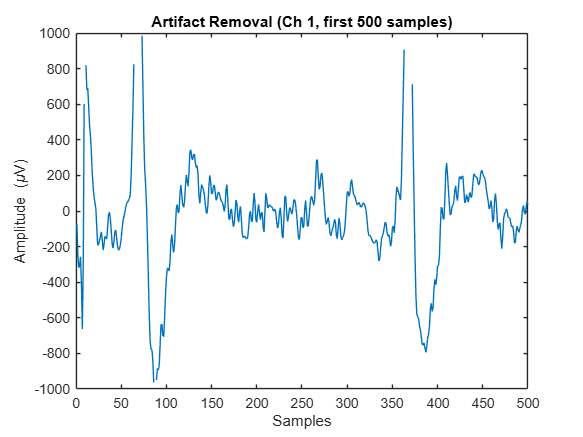


cleanedData = filteredData;
cleanedData(artifactMask) = NaN;

figure('Name','Artifact Removal','NumberTitle','off');
ch1Snippet = cleanedData(1,1:min(500,timePoints));
plot(ch1Snippet);
title('Artifact Removal (Ch 1, first 500 samples)');
xlabel('Samples'); ylabel('Amplitude (\muV)');


normalizedData = zeros(size(cleanedData));
for ch = 1:channels
    chanData = cleanedData(ch,:);
    goodIdx = ~isnan(chanData);
    mu = mean(chanData(goodIdx));
    sigmaVal = std(chanData(goodIdx));
    if sigmaVal < 1e-10
        sigmaVal = 1;  
    end
    normalizedData(ch, goodIdx) = (chanData(goodIdx) - mu)/sigmaVal;
end


ch1Good = normalizedData(1,~isnan(normalizedData(1,:)));
fprintf('Normalized Ch1 -> mean=%.3f, std=%.3f\n', mean(ch1Good), std(ch1Good));

Normalized Ch1 -> mean=0.000, std=0.998


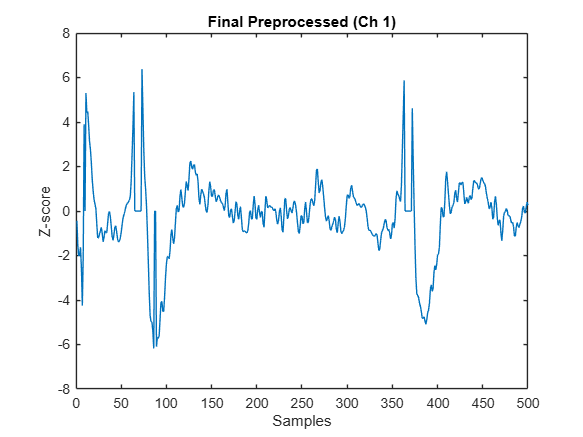


figure('Name','Final Preprocessed Data','NumberTitle','off');
plot(normalizedData(1,1:min(500,timePoints)));
xlabel('Samples'); ylabel('Z-score');
title('Final Preprocessed (Ch 1)');